## Homework 3.1

clear all;
close all;
clc;

### a. Let $\phi(x) = x - x^3$, which admits $\xi=0$ as a fixed point.

Compute $\phi'(\xi)$ and test the convergence of the sequence $x^{(x+1)}=\phi(x^{(k)})$ for $x^{(0)} \in [-1,1]$

Let's plot $\phi(x)$ and $\phi'(x)$

phi = @(x) x - x.^3;
dphi = @(x) 1 - 3*x.^2;

x = linspace(-2, 2, 10000);

dphi(0)

ans = 1

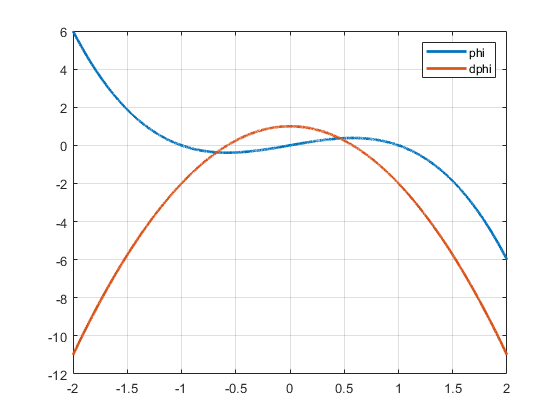


figure();
plot(x, phi(x), 'LineWidth', 2);
hold on;
plot(x, dphi(x), 'LineWidth', 2);
hold off;

grid on;
legend({'phi', 'dphi'}, 'Location', 'northeast');

tol = 10e-12;
maxit = 10e6;


$$x^{(0)} = -1$$


x0 = -1;
[xi, x_iter] = fixed_point(phi, x0, tol, maxit)

xi = 0

x_iter =     -1     0     0



$$x^{(0)} = 1$$


x0 = 1;
[xi, x_iter] = fixed_point(phi, x0, tol, maxit)

xi = 0

x_iter =      1     0     0



$$x^{(0)}=0.5$$


x0 = 0.5;
[xi, x_iter] = fixed_point(phi, x0, tol, maxit)

xi = 2.2361e-04

x_iter =     0.5000    0.3750    0.3223    0.2888    0.2647    0.2462    0.2312    0.2189    0.2084    0.1993    0.1914    0.1844    0.1781    0.1725    0.1674    0.1627    0.1584    0.1544    0.1507    0.1473    0.1441    0.1411    0.1383    0.1356    0.1332    0.1308    0.1286    0.1264    0.1244    0.1225    0.1206    0.1189    0.1172    0.1156    0.1141    0.1126    0.1111    0.1098    0.1084    0.1072    0.1059    0.1048    0.1036    0.1025    0.1014    0.1004    0.0994    0.0984    0.0974    0.0965


### b. Let $\phi(x) = x + x^3$, which admits $\xi=0$ as a fixed point.

Compute $\phi'(\xi)$ and test the convergence of the sequence $x^{(x+1)}=\phi(x^{(k)})$ for $x^{(0)} \in [-1,1]$

Let's plot $\phi(x)$ and $\phi'(x)$

phi = @(x) x + x.^3;
dphi = @(x) 1 + 3*x.^2;

x = linspace(-2, 2, 10000);

dphi(0)

ans = 1

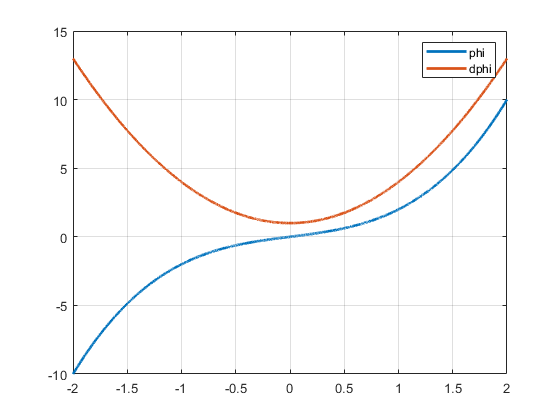


figure();
plot(x, phi(x), 'LineWidth', 2);
hold on;
plot(x, dphi(x), 'LineWidth', 2);
hold off;

grid on;
legend({'phi', 'dphi'}, 'Location', 'northeast');

tol = 10e-12;
maxit = 10e6;


$$x^{(0)} = -1$$


x0 = -1;
[xi, x_iter] = fixed_point(phi, x0, tol, maxit)

xi = -Inf

x_iter = 	1.0e+243 *

   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -2.2389      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf



$$x^{(0)} = 1$$


x0 = 1;
[xi, x_iter] = fixed_point(phi, x0, tol, maxit)

xi = Inf

x_iter = 	1.0e+243 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.2389       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf



$$x^{(0)}=0.5$$


x0 = 0.5;
[xi, x_iter] = fixed_point(phi, x0, tol, maxit)

xi = Inf

x_iter = 	1.0e+172 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    6.3754       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf


In this second case it's clear that the procedure will not converge. Since $\phi(\xi) = 1$ we have no guatantees that the procedure will converge and, in fact, from the results shown above we see that the procedure diverges.

### Functions

function [xi, x_iter] = fixed_point(phi, x0, tol, maxit)

  x_iter(1) = x0;

  for iter = 1:maxit

    x_iter(iter+1) = phi(x_iter(iter));

    if (abs (x_iter(iter+1) - x_iter(iter)) < tol)
      break;
    end

  end
  
  xi = x_iter(end);

end